# Cálculos para el Control ergódico de un sistema dinámico, Algoritmo Spectral Multiscale Coverage (SMC)

close all
clear
clc

Se considera $$\Omega = [L_1^l, L_1^u] \times \cdots \times [L_n^l, L_n^u] $$ un espacio de búsqueda $n$ dimensional rectangular y euclidiano, donde $$L_i^l$$ y $$L_i^u$$ son los límites inferior y superior de la $i$-ésima dimensión, respectivamente. Se denota el espacio de la tarea $\mathbf{x}={\left\lbrack \begin{array}{cccc}
x_1  & x_2  & \cdots  & x_n 
\end{array}\right\rbrack }^T \in \Omega$, y una distribución espacial de referencia $$\Phi(\mathbf{x})$$


n = 2; % Número de dimensiones

%Parámetros del espacio de búsqueda \Omega = [L_1_l, L_1_u] \times [L_2_l, L_2_u]
% con \mathbf{x} = [x_1 x_2]^T
L_1_l = 0.5;
dx_1 = 0.01;
L_1_u = 1.5;

L_2_l = 0.5;
dx_2 = 0.01;
L_2_u = 1.5;

x_1 = (L_1_l:dx_1:L_1_u)';
x_2 = (L_2_l:dx_2:L_2_u)';

%x_vect = [x_1, x_2];

%vector de límites inferior y superiores de las dimensiones
L_i_l = [L_1_l, L_2_l];
L_i_u = [L_1_u, L_2_u];

% Gaussian Mixture distribution (PDF de REFERENCIA)
mu_1 = [0.9, 0.9]; %Media del primer Gaussiano
mu_2 = [0.8, 1.2];
mu_3 = [1.3, 1];

Mu = [mu_1; mu_2; mu_3];

Cov_1 = [0.01, 0.004;
         0.004, 0.01];
Cov_2 = [0.005, -0.003;
         -0.003, 0.005];
Cov_3 = [0.008, 0.0;
         0.0, 0.004];

Sigma = cat(3,Cov_1,Cov_2,Cov_3);

proporciones = [0.5, 0.2, 0.3]; % Pesos sobre cada Gaussiano (la suma de los pesos debe dar 1)

gm_dist = gmdistribution(Mu, Sigma, proporciones); %Genera el objeto de la distribución

[x_1_grid, x_2_grid] = meshgrid(x_1, x_2);

Omega = [reshape(x_1_grid,[],1), reshape(x_2_grid,[],1)]; %Describe todos las coordenadas en el espacio de búsqueda

Phi_x = pdf(gm_dist, Omega);


#### La distribución de referencia $$\Phi(\mathbf{x})$$ se puede descomponer como 

#### 
$$\Phi(\mathbf{x}) = \sum_{^j\mathbf{k} \in \mathcal{K}} \phi_{(^j\mathbf{k})} f_{(^j\mathbf{k})} (\mathbf{x})$$


#### donde $$\mathcal{K} = \left\{ {^j\mathbf{k}} | j = 0,1,\ldots, K^n-1 \right\}$$ es el conjunto de todas las combinaciones del vector de índices ${^j\mathbf{k}} = $${\left\lbrack \begin{array}{cccc}
k_1  & k_2  & \cdots  & k_n 
\end{array}\right\rbrack }^T$ con $$k_i \in [0,1,\ldots,K-1], i = 1,2,\ldots, n$$. Y $K$ es el número de coeficientes (y funciones) de Fourier que se quieren calcular por dimensión.

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%
%%%Cálculo de los coeficientes de Fourier para la PDF de referencia%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

K = 25; %Número de coeficientes por dimensión

%Al final, se tendrán K^n coeficientes en total para toda la función de
%referencia \Phi(\mathbf{x})

%Cálculo de los valores que puede tomar k_i
k_1 = (0:K-1)';
k_2 = (0:K-1)';

[k_1_grid, k_2_grid] = meshgrid(k_1, k_2);

%K_cal es el conjunto de todas las ^j\mathbf{k}, con (K^n) elementos
K_cal = [reshape(k_1_grid,1,[]); reshape(k_2_grid,1,[])];

La función ortonormal de Fourier se calcula con:


$$f_{(^j\mathbf{k})}(\mathbf{x}) = \frac{1}{h_{(^j\mathbf{k})}(\mathbf{x})} \underbrace{ \prod_{i=1}^n \cos \left( \frac{k_i \pi}{L_i^u-L_i^l} \left( x_i - L_i^l \right)  \right) }_{\tilde{f}_{(^j\mathbf{k})}(\mathbf{x})}$$


$\tilde{f}_{(^j\mathbf{k})}(\mathbf{x})$ es la función ortogonal de Fourier, y se normaliza con 


$$h_{(^j\mathbf{k})} (\mathbf{x}) = \sqrt{ \int_\Omega \prod_{i=1}^n \cos ^2 \left( \frac{k_i \pi}{L_i^u - L_i^l} \left( x_i - L_i^l \right) \right) d\mathbf{x} } = \sqrt{ \int_\Omega \tilde{f}_{(^j\mathbf{k})}^2(\mathbf{x}) d\mathbf{x} }$$


al final se tendrán $K^n$ escalares en un conjunto que llamaremos $h_{\mathcal{K}}$, y se puede definir como $$h_{\mathcal{K}} = \left\{ h_{(^j\mathbf{k})}(\mathbf{x}) | j = 0,1,\ldots, K^n-1 \right\} $$, con $h_{(^j\mathbf{k})}(\mathbf{x})$ escalares. Se define también el conjunto de todas las funciones ortonormales de Fourier en $\mathbf{x}$ como $f_{\mathcal{K}}(\mathbf{x}) = \left\{ f_{(^j \mathbf{k})}(\mathbf{x}) | j = 0,1,\ldots, K^n-1 \right\}$.

Los coeficientes de Fourier para $\Phi(\mathbf{x})$ se calculan con: 


$$\phi_{(^j\mathbf{k})} = \int_\Omega \Phi(\mathbf{x}) f_{(^j\mathbf{k})} (\mathbf{x}) d\mathbf{x}$$


%%%%%% Cálculo de coeficientes usando un For Loop
% 
% %Registro para guardar los coeficientes
% phi_k_reg = zeros(size(K_cal,2), 1);
% 
% %Registro para guardar las funciones evaluadas en \mathbf{x}, cada columna
% %corresponde a la j-ésima combinacion de \mathbf{k}. Las filas corresponden
% %a cada punto discreto en el espacio, y las columnas a la combinación de k.
% f_k_reg = zeros(height(Omega), size(K_cal,2));
% 
% %Registro para el término normalizador (h_{\mathbf{k}})
% h_k_reg = zeros(size(K_cal,2),1);
% 
% % Este for recorre la j-ésima combinación para k
% for j = 1:size(K_cal,2)
% 
%     k_vect_j = K_cal(:,j)';
% 
%     % función ortogonal \tilde{f}_{\mathbf{k}}
%     f_tilde_k_j = prod(cos( k_vect_j.*pi.*(Omega - L_i_l)./(L_i_u - L_i_l) ), 2);
% 
%     % Término normalizador (h_{\mathbf{k}}) = un escalar por cada j-ésima
%     % combinación de \mathbf{k}
%     h_k_j = sqrt(sum(f_tilde_k_j .^2) * dx_1 * dx_2);
% 
%     % función ortonormal f_{\mathbf{k}} correspondiente a la j-ésima
%     % combinación del vector k (^j \mathbf{k}), evaluada en todo el espacio U.
%     f_k_j = f_tilde_k_j ./ h_k_j;
% 
%     % Coeficientes \phi_{^j \mathbf{k}}, la integral se aproxima con Riemann
%     phi_k_j = sum(Phi_x .* f_k_j)*dx_1*dx_2;
% 
%     % Se guardan los coeficientes, las funciones ortonormales y los
%     % términos normalizadores en registros
%     h_k_reg(j) = h_k_j;
%     f_k_reg(:,j) = f_k_j;
%     phi_k_reg(j) = phi_k_j;
% 
% end


%%%%%%%% Calculo de coeficientes SIN un For loop %%%%%%%%%
f_tilde_k = prod(cos(repmat(reshape(K_cal,1,n,K^n), [height(Omega), 1, 1]).*...
    repmat(pi.*(Omega - L_i_l)./(L_i_u - L_i_l), [1, 1, K^n])), 2);
h_k = sqrt(sum(f_tilde_k.^2) * dx_1 * dx_2);
f_k = f_tilde_k ./ repmat(h_k, [height(Omega),1,1]);
phi_k = sum( repmat(Phi_x,[1,1,K^n]) .* f_k)*dx_1*dx_2;

%Registros
h_Kcal = reshape(h_k, K^n, 1);
f_Kcal = reshape(f_k, height(Omega), K^n);
phi_Kcal = reshape(phi_k, K^n, 1);
h_k_reg = h_Kcal;
f_k_reg = f_Kcal;
phi_k_reg = phi_Kcal;


La referencia se puede reconstruir para verificar la verosimilitud de los coeficientes:


$$\Phi(\mathbf{x}) \approx \sum_{j = 0}^{K^n - 1} \phi_{(^j\mathbf{k})} f_{(^j\mathbf{k})} (\mathbf{x}) = \phi_{(^0\mathbf{k})}   f_{(^0\mathbf{k})} (\mathbf{x})  + \cdots + \phi_{(^{K^n - 1}\mathbf{k})} f_{(^{K^n - 1}\mathbf{k})} (\mathbf{x})$$


%% Reconstrucción de la PDF de referencia para verificación de coeficientes

Phi_x_reconstructed = zeros(height(Omega),1);

for i = 1:height(phi_k_reg)
    Phi_x_reconstructed = Phi_x_reconstructed + phi_k_reg(i)*f_k_reg(:,i);
end

#### Defínase una trayectoria $\mathbf{X}_e(t) = [x_{e_1}, x_{e_2}, \ldots, x_{e_n } ]^T \in \mathbb{R}^n$ y la variable temporal $t \in [t_0 = 0,t_f]$ con $t_f$ el tiempo final de ejecución, y en el ámbito discreto, $t \in [t_0,t_1,t_2,\ldots, t_f] = [0, T_s, 2T_s, \ldots, (n_s-1)T_s]$ con $T_s$ el tiempo de muestreo, y $n_s$ el número total de muestras.

%% Condiciones Iniciales y parámetros       
T = 0.01;                  % Paso
t_f = 10;     % Tiempo de simulación
t = (0:T:t_f)';

%% Trayectoria aleatoria (hypotrochoid)

D = 0.3;
R = D;
r = 3*D/5;
x_c = (L_1_u - L_1_l)/2 + L_1_l;
y_c = (L_2_u - L_2_l)/2 + L_2_l;

x_t = x_c + (R - r)*cos(pi*t) + D*cos((R - r)/r * pi*t);
y_t = y_c + (R - r)*sin(pi*t) - D*sin((R - r)/r * pi*t);

%Trayectoria Circulo

% r_d = 0.4;
% x_c = (L_1_u - L_1_l)/2 + L_1_l;
% y_c = (L_2_u - L_2_l)/2 + L_2_l;
%
% x_t = x_c + r_d*cos(delta_t);
% y_t = y_c + r_d*sin(delta_t);


Considere la distribución empírica de la trayectoria $\mathbf{X_e} (t)$:


$$C(\mathbf{x}) = \frac{1}{t_f - t_0} \int_{t_0} ^ {t_f} \delta \left( \mathbf{x} - \mathbf{X_e} (\tau) \right) d \tau$$


Se puede descomponer como


$$C(\mathbf{x}) = \sum_{j = 0 }^{K^n-1} c_{(^j \mathbf{k})} f_{(^j \mathbf{k})}(\mathbf{x})$$


donde $c_{(^j \mathbf{k})}$ son los coeficientes de Fourier sobre el vector de coeficientes $^j \mathbf{k}$, y $f_{(^j \mathbf{k})}(\mathbf{x})$ (que ya se tiene disponible, se calculó previamente para $\Phi(\mathbf{x})$ ). Los coeficientes se obtienen de hacer el producto interno como sigue:


$$c_{(^j \mathbf{k})} = \langle C(\mathbf{x}), f_{(^j \mathbf{k})}(\mathbf{x}) \rangle = \int_\Omega \left( \frac{1}{t_f - t_0} \int_{t_0} ^ {t_f} \delta \left( \mathbf{x} - \mathbf{X_e} (\tau) \right) d \tau \right) f_{(^j \mathbf{k})}(\mathbf{x}) d\mathbf{x}, \quad \forall j$$


Esto es:


$$c_{(^j \mathbf{k})} = \frac{1}{t_f - t_0} \int_0 ^{t_f} f_{(^j \mathbf{k})}(\mathbf{X_e}(\tau)) d\tau$$


las funciones ortonormales de Fourier $f_{(^j \mathbf{k})}(\mathbf{X_e}(\tau))$ se calculan en línea y se evalúa sólo en la posición actual de la trayectoria $\mathbf{X_e}(t)$ y no en todo el espacio de la tarea $\mathbf{x}$.


$$f_{(^j \mathbf{k})}(\mathbf{X_e}(t)) = \frac{1}{h_{(^j\mathbf{k})}(\mathbf{x})} \underbrace{ \prod_{i=1}^n \cos \left( \frac{k_i \pi}{L_i^u-L_i^l} \left( x_{e_i}(t) - L_i^l \right)  \right) }_{\tilde{f}_{(^j\mathbf{k})}(\mathbf{X_e}(t))}$$


Con $\tilde{f}_{(^j\mathbf{k})}(\mathbf{X_e}(t))$ la función ortogonal de Fourier, y se normaliza con el término $h_{(^j\mathbf{k})} (\mathbf{x})$ que se calculó previamente para $\Phi(\mathbf{x})$. Tome en cuenta que los coeficientes de la trayectoria en cierto tiempo $(t_i)$ considera el resultado anterior en $(t_{i-1} )$,


$$c_{ ( ^j \mathbf{k}) }(t_i) = c_{(^j \mathbf{k})}(t_{i-1}) + \frac{1}{t_f - t_0} \int_{t_i}^{t_{i+1}} f_{(^j\mathbf{k})}(\mathbf{X_e}(t_i)) d\tau \approx c_{(^j \mathbf{k})}(t_{i-1}) + \frac{T_s}{t_f - t_0} f_{(^j\mathbf{k})}(\mathbf{X_e}(t_i))$$


son las entradas de todo el registro de coeficientes $$c_\mathcal{K}(t_i) = [
    c_{(^0 \mathbf{k})}(t_i) \quad c_{(^1 \mathbf{k})}(t_i) \quad \cdots \quad c_{(^(K^n-1) \mathbf{k})} (t_i)
]^T$$ en un tiempo $t_i$

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%
%Cálculo de los coeficientes de Fourier de la distribución empírica que
%genera la trayectoria
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Registro para guardar los valores de las funciones de Fourier sobre la
%trayectoria, las filas corresponden a las combinaciones de \mathbf{k}, y
%las columnas corresponden a los pasos temporales
f_k_traj_reg = zeros(size(K_cal, 2), length(t));

%Registro para guardar los vectores de coeficientes en todo t
c_k_reg = zeros(size(K_cal, 2), length(t));

%Inicialización de los coeficientes para la trayectoria, se generan los K^n
%coeficientes en cada paso de muestreo t
c_k_i = zeros(size(K_cal, 2), 1);

for i = 1:length(t)
    
    X_e = [x_t(i), y_t(i)]; %Vector fila, para que los cálculos coincidan en dimensión

    %función ortonormal para el par de puntos actuales (x(t),y(t)) sobre
    %todas las combinaciones de \mathbf{k}
    f_k_traj_i = prod(cos( K_cal'.*pi.*(X_e - L_i_l)./(L_i_u - L_i_l) ), 2) ./ h_k_reg ;
    
    %Generación y actualización de los coeficientes: la normalización se
    %hace con respecto al tiempo final de la integral actual (t_act + T)
    c_k_i = c_k_i + (f_k_traj_i*T)/t_f ;

    %Registros
    f_k_traj_reg(:,i) = f_k_traj_i;
    c_k_reg(:,i) = c_k_i;

end


% Cálculo de los coeficientes de la trayectoria calculando h_k en línea
% 
% h_k_traj_reg = zeros(length(t), 1);
% 
% for i = 1:length(t)
%     X_e = [x_t(i), y_t(i)]; %Vector fila, para que los cálculos coincidan en dimensión
% 
%     % función ortogonal \tilde{f}_{\mathbf{k}} para el par de puntos actuales (x(t),y(t))
%     f_tilde_k_traj_i = prod(cos( K_cal'.*pi.*(X_e - L_i_l)./(L_i_u - L_i_l) ), 2);
% 
%     % Término normalizador (h_{\mathbf{k}}) = un escalar por cada j-ésima
%     % combinación de \mathbf{k}
%     h_k_traj_i = sqrt(sum(f_tilde_k_traj_i .^2) * dx_1 * dx_2);
% 
%     % función ortonormal f_{\mathbf{k}} correspondiente a la j-ésima
%     % combinación del vector k (^j \mathbf{k}), evaluada en todo el espacio U.
%     f_k_traj_i = f_tilde_k_traj_i ./ h_k_traj_i;
% 
%     %Generación y actualización de los coeficientes: la normalización se
%     %hace con respecto al tiempo final de la integral actual (t_act + T)
%     c_k_i = c_k_i + (f_k_traj_i*T)/t_f ;
% 
%     %Registros
%     f_k_traj_reg(:,i) = f_k_traj_i;
%     c_k_reg(:,i) = c_k_i;
%     h_k_traj_reg(i) = h_k_traj_i;
% end

La distribución empírica de la trayectoria de reconstruye con


$$C(\mathbf{x}) = \sum_{j = 0 }^{K^n-1} c_{(^j \mathbf{k})} f_{(^j \mathbf{k})}(\mathbf{x})$$


%% Reconstrucción de la distribución empírica que genera la trayectoria C(\mathbf{x})

C_x = zeros(height(Omega), 1);
C_x_reg = zeros(height(Omega), length(t));

for i = 1:length(t)
    
    %Genera la distribución en t(i), en total se tienen tantas
    %distribuciones como muestras de tiempo
    C_x_i = zeros(height(Omega), 1);
    for j = 1:size(K_cal, 2)
        C_x_i = C_x_i + c_k_reg(j,i)*f_k_reg(:,j);
    end
    
    %Se suman todas las distribuciones generadas en cada muestra
    C_x = C_x + C_x_i;

    %Se registra
    C_x_reg(:,i) = C_x;

end

#### La métrica ergódica se define como:

#### 
$$\varepsilon \left( \Phi(\mathbf{x}), \mathbf{X_e}(t) \right) = \sum_{^j \mathbf{k} \in \mathcal{K}} \Lambda_{(^j\mathbf{k})} \left( c_{(^j\mathbf{k})} - \phi_{(^j\mathbf{k})} \right)^2$$


#### Donde $\Lambda_{(^j\mathbf{k})} = \left( 1 + \| {^j\mathbf{k}} \| \right)^{- \frac{n + 1}{2}}$ es un coeficiente que da mayor importancia a los modos de baja frecuencia, el operador $\| \cdot \|$ se refiere a la norma 2 o norma euclidiana. 

#### Vea que $\Lambda_{(^j\mathbf{k})}$ se puede pre-calcular, sólo necesita la dimensión del espacio de búsqueda $n$ y los vectores de índices $^j\mathbf{k}$. Además, los coeficientes $\phi_{(^j\mathbf{k})}$ son constantes, y se tendrán tantos coeficientes como vectores de índices ($K^n$ elementos). Lo que se va generando en línea, son los coeficientes $c_{(^j\mathbf{k})}$, pues se generan $K^n$ coeficientes en cada paso de muestreo de la trayectoria $\mathbf{X_e}(t)$.

%% Ergodic Metric
%También se puede generar justo después de ir generando los coeficientes
%para la trayectoria empírica, en el For de arriba

Epsilon_t_reg = zeros(length(t), 1);

%Cálculo de todas las Lambdas_{\mathbf{k}}
p = 2; %norma 2
Lambda_k = (1 + vecnorm(K_cal, p, 1)').^(-(n + 1)/2);

for i = 1:length(t)

    %Métrica calculada en cada t
    Epsilon_t = sum( Lambda_k .* (c_k_reg(:,i) - phi_k_reg).^2 ); 

    %Registro de la métrica en todo el historial de tiempo
    Epsilon_t_reg(i) =  Epsilon_t;

end


# Gráficas

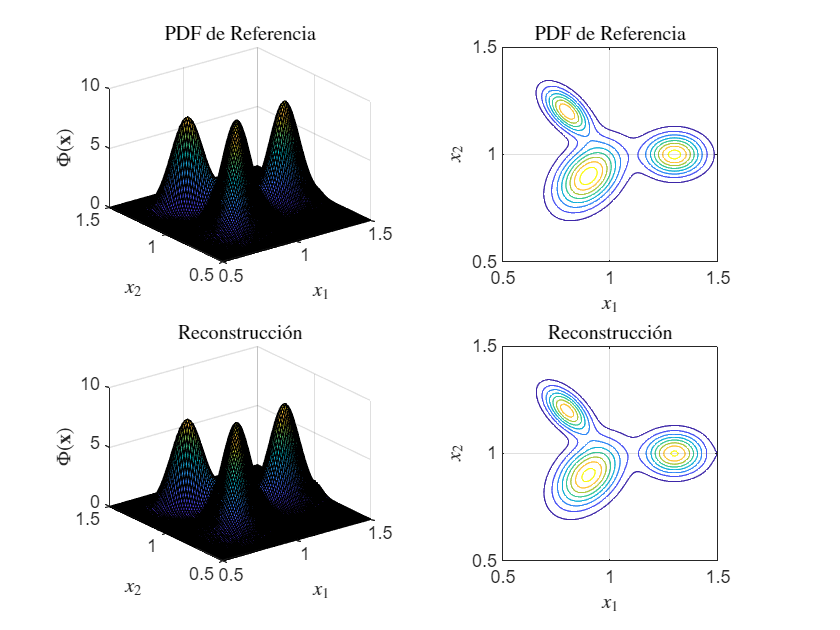

% Distribución de Referencia

figure(1)
subplot(2,2,1);
surf(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
axis([L_1_l, L_1_u, L_2_l, L_2_u, 0, 10])
title("PDF de Referencia",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$\Phi(\mathbf{x})$','Interpreter','latex')
%axis equal
grid on

subplot(2,2,2);
contour(x_1_grid, x_2_grid, reshape(Phi_x, length(x_2), length(x_1)))
axis([L_1_l, L_1_u, L_2_l, L_2_u])
title("PDF de Referencia",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
axis equal
grid on

subplot(2,2,3);
surf(x_1_grid, x_2_grid, reshape(Phi_x_reconstructed, length(x_2), length(x_1)))
axis([L_1_l, L_1_u, L_2_l, L_2_u, 0, 10])
title("Reconstrucci\'on",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$\Phi(\mathbf{x})$','Interpreter','latex')
%axis equal
grid on

subplot(2,2,4);
contour(x_1_grid, x_2_grid, reshape(Phi_x_reconstructed, length(x_2), length(x_1)))
axis([L_1_l, L_1_u, L_2_l, L_2_u, 0, 10])
title("Reconstrucci\'on",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
axis equal
grid on

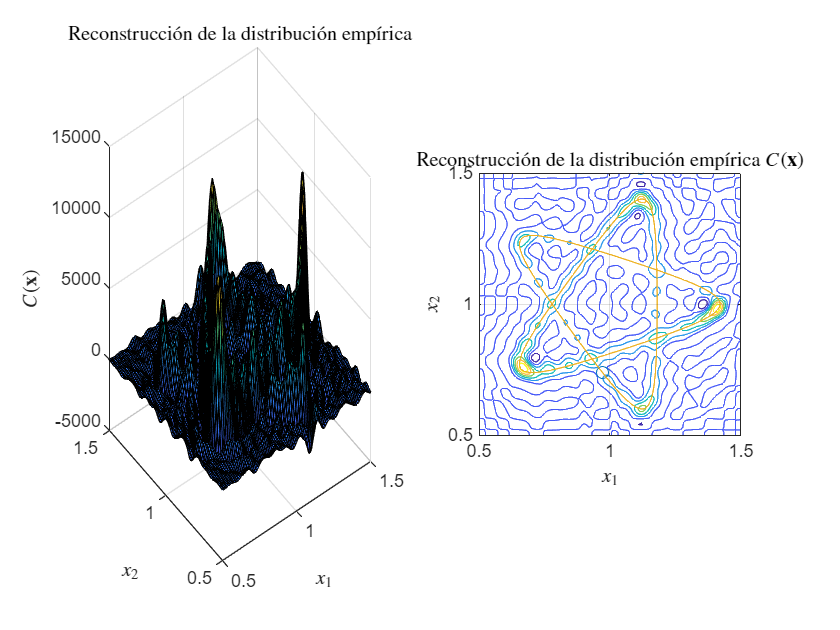

% Distribución empírica y trayectoria

figure(2)
subplot(1,2,1);
surf(x_1_grid, x_2_grid, reshape(C_x, length(x_2), length(x_1)))
xlim([L_1_l, L_1_u])
ylim([L_2_l, L_2_u])
title("Reconstrucci\'on de la distribuci\'on emp\'irica",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
zlabel('$C(\mathbf{x})$','Interpreter','latex')
grid on

subplot(1,2,2);
contour(x_1_grid, x_2_grid, reshape(C_x, length(x_2), length(x_1)))
axis([L_1_l, L_1_u, L_2_l, L_2_u])
title("Reconstrucci\'on de la distribuci\'on emp\'irica $C(\mathbf{x})$",'Interpreter','latex')
xlabel('$x_1$','Interpreter','latex')
ylabel('$x_2$','Interpreter','latex')
axis equal
grid on
hold on
comet(x_t,y_t)
hold off

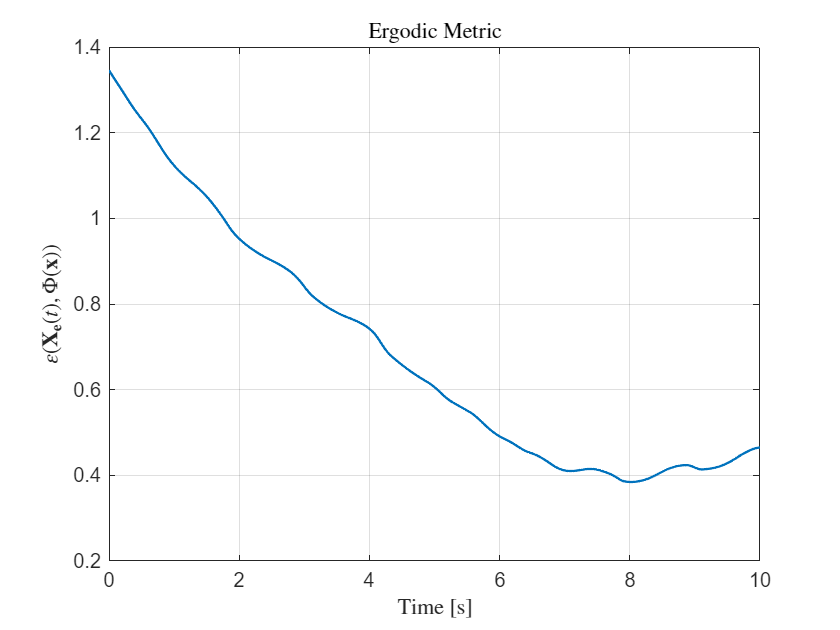

%Ergodic Metric

figure(3)
plot(t, Epsilon_t_reg, "LineWidth",1.2)
title("Ergodic Metric",'Interpreter','latex')
xlabel('Time [s]','Interpreter','latex')
ylabel('$\varepsilon \left( \mathbf{X_e}(t), \Phi(\mathbf{x}) \right) $','Interpreter','latex')
grid on


%% Gráficas animadas

%Distribución empírica

figure(4)

for i = 1:length(t)

    subplot(1,2,1);
    surf(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)))
    view([-38 63])
    xlim([L_1_l, L_1_u])
    ylim([L_2_l, L_2_u])
    title("Reconstrucci\'on de la distribuci\'on emp\'irica",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    zlabel('$C(\mathbf{x})$','Interpreter','latex')
    axis tight
    shading flat
    colormap default
    grid on

    subplot(1,2,2);
    contour(x_1_grid, x_2_grid, reshape(C_x_reg(:,i), length(x_2), length(x_1)))
    axis([L_1_l, L_1_u, L_2_l, L_2_u])
    title("Reconstrucci\'on de la distribuci\'on emp\'irica $C(\mathbf{x})$",'Interpreter','latex')
    xlabel('$x_1$','Interpreter','latex')
    ylabel('$x_2$','Interpreter','latex')
    axis equal
    grid on
    hold on
    plot(x_t(i), y_t(i), 'ko', 'LineWidth', 1.5)
    hold off

    drawnow limitrate

end